% ok lets gooooooooooooo!!!!!
% testim = imread("CV_zebracrossing_images/pic1.jpg");
% imshow(testim)

Imfolder = 'CV_zebracrossing_images';
if ~isfolder(Imfolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', Imfolder);
  uiwait(warndlg(errorMessage));
  return;  
end

% Get a list of all image files in the folder
imageFiles = dir(fullfile(Imfolder, '*.jpg')); 

imnum = numel(imageFiles)

imnum = 50

stockImages = cell(1, imnum);
images = cell(1, imnum);
imheight = zeros(1, imnum);
imcropheight = zeros(1, imnum);

for idx = 1:imnum
    filename = fullfile(Imfolder, imageFiles(idx).name);
    stockImages{idx} = imread(filename);
    %von mir hinzugefügte Zeilen
    images{idx}=imresize(stockImages{idx},[300,600]);
    %imwrite(k,filename,"jpg");
    %[~, imheight(idx), ~] = size(images{idx}); % Extract height of each image
    %imcropped{idx} = imcrop(images{idx}, [1 1 size(images{idx}, 2) imheight(idx) * 0.5]);

    %my new code:
%     %create a grayscale image 
%     grayImage = rgb2gray(imcropped{idx});
%     %im_h = histogram(grayImage(grayImage>0));
%     %calculate verage value
%     durchschnitt = mean(grayImage(:));
% 
%     %defining threshold & apllying it to images
%     kThreshold = durchschnitt*1.7;
%     zebraCrossing = grayImage > kThreshold;
%     %displaying it
%     figure(1);
%     subplot(7, 8, idx);
%     imshow(zebraCrossing);
end

% for i = 1:imnum
%     imshow(imcropped{i});
% end

code snipped for threshold adjustment on only one pic

%create a grayscale image 
grayImage = rgb2gray(images{47});

%get the histogram and display both
figure(1);
subplot(1, 2, 1);
im_h = histogram(grayImage(grayImage>0));
hold on
%calculate and display average
durchschnitt = mean(grayImage(:))

durchschnitt = 39.6799

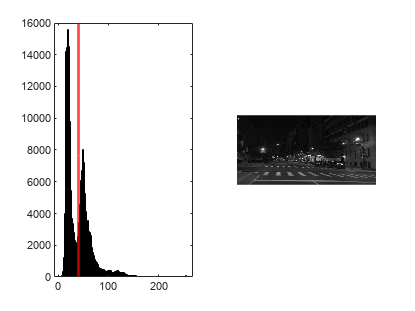

xline(durchschnitt, 'Color', 'r', 'LineWidth', 2);

% Display the gray scale image.
subplot(1, 2, 2);
imshow(grayImage, []);

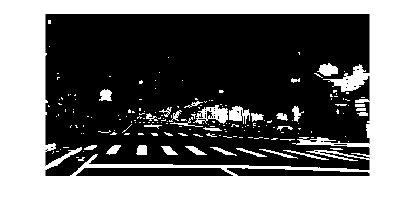



kThreshold = durchschnitt*1.7;
zebraCrossing = grayImage > kThreshold;

figure(2);
subplot(1, 1, 1);
imshow(zebraCrossing);